# polyvalOrtho

polyvalOrtho evaluates the orthogonal polynomial created from polyfitOrtho

## Inputs

- **coefficients** - Structure created from polyfitOrtho. 

- **x** - double of any size. points to evaluate the polynomial. 

## Outputs

- **y** - double. Same size as x. Values of polynomial evaluated at x.

## Description

polyvalOrtho is complementary function to polyfitOrtho to evaluated the orthogonal polynomial created with polyfitOrtho. 

The time complexity of this function is O(k*m) where k is the order of the polynomial and m is the number of points in x. 

## Example

Fit a 186th degree polynomial to the Runge function on 500 Chebyshev points. The Chebyshev points are chosen because high degree interpolating polynomials are known to converge to the Runge function.

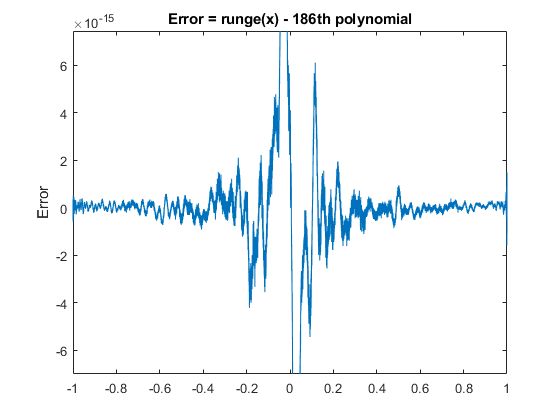

runge = @(x) 1./(1+25*x.^2);
theta = linspace(pi,0,500);
x = cos(theta); % Chebyshev points
y = runge(x);
k = 186;
coefficientsAndResults = polyfitOrtho(x,y,k);
figure;
fplot(@(x) runge(x)-polyvalOrtho(coefficientsAndResults,x),[-1 1])
ylabel('Error')
title(sprintf('Error = runge(x) - %dth polynomial',k))

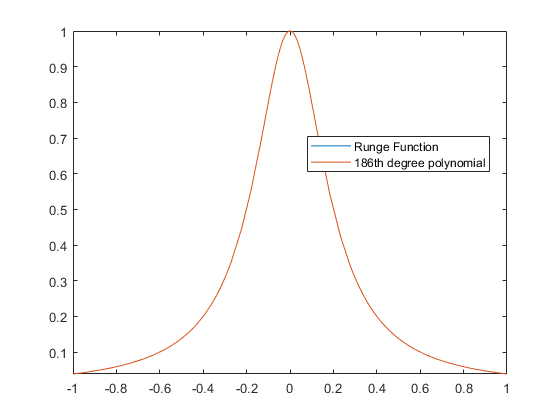

figure;
fplot(@(x) runge(x),[-1 1])
hold all;
fplot(@(x) polyvalOrtho(coefficientsAndResults,x),[-1 1])
legend(["Runge Function", sprintf("%dth degree polynomial",k)],'location','best')

## References

The algorithm and nomenclature comes from Forsythe 1957. 

[1] Forsythe, George E. "Generation and use of orthogonal polynomials for data-fitting with a digital computer." Journal of the Society for Industrial and Applied Mathematics 5.2 (1957): 74-88.

See also polyvalOrtho, polyfit, polyval.